# **UE1 USRP B210  Receiver **

## Set OFDM Frame Parameters

% Clear all the function data as they contain some persistent variables
clear;
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset getTrParamsforSpecificBS_id;
close all;
% 第一部分可以认为是控制基站的功能
% The chosen set of OFDM parameters overall for all BSs:
overAllOfdmParams.online_BS               = 1;              % number of online data BS 
overAllOfdmParams.FFTLength               = 256;              % FFT length
overAllOfdmParams.CPLength                = ceil(overAllOfdmParams.FFTLength*0.25);   % Cyclic prefix length
overAllOfdmParams.Subcarrierspacing       = 30e3;               % Sub-carrier spacing of 30 KHz
total_RB                                  = 17;                                % User input Resource block number

% 调用calculateRBFinal函数确保最终的RB确定的子载波总数能够被pilot subcarrier spacing整除
[RB_verified, MaxRB] = calculateRBFinal(overAllOfdmParams, total_RB);
% 补充，其实新的算法不需要这个强限制，直接传入total RB即可

% check if RB_verified exceed MaxRB
if total_RB > MaxRB || RB_verified > MaxRB
    error('Error: Defined RB (%d) exceeds the system maximum allowed RB (%d). ', RB_verified, MaxRB);
end

overAllOfdmParams.total_RB                     = total_RB;
overAllOfdmParams.total_NumSubcarriers         = overAllOfdmParams.total_RB*12;                  % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
overAllOfdmParams.guard_interval = (overAllOfdmParams.FFTLength - overAllOfdmParams.total_NumSubcarriers) / 2;     % Guard interval, 单侧的空载波
% check if NumSubcarriers less than FFTLength
if overAllOfdmParams.total_NumSubcarriers > overAllOfdmParams.FFTLength
    error('Total NumSubcarriers: (%d) exceeds Total FFTLength: (%d), which is not allowed. Please reduce the value of RB.', ...
        overAllOfdmParams.total_NumSubcarriers, overAllOfdmParams.FFTLength);
end


## Initialize Receiver Parameters

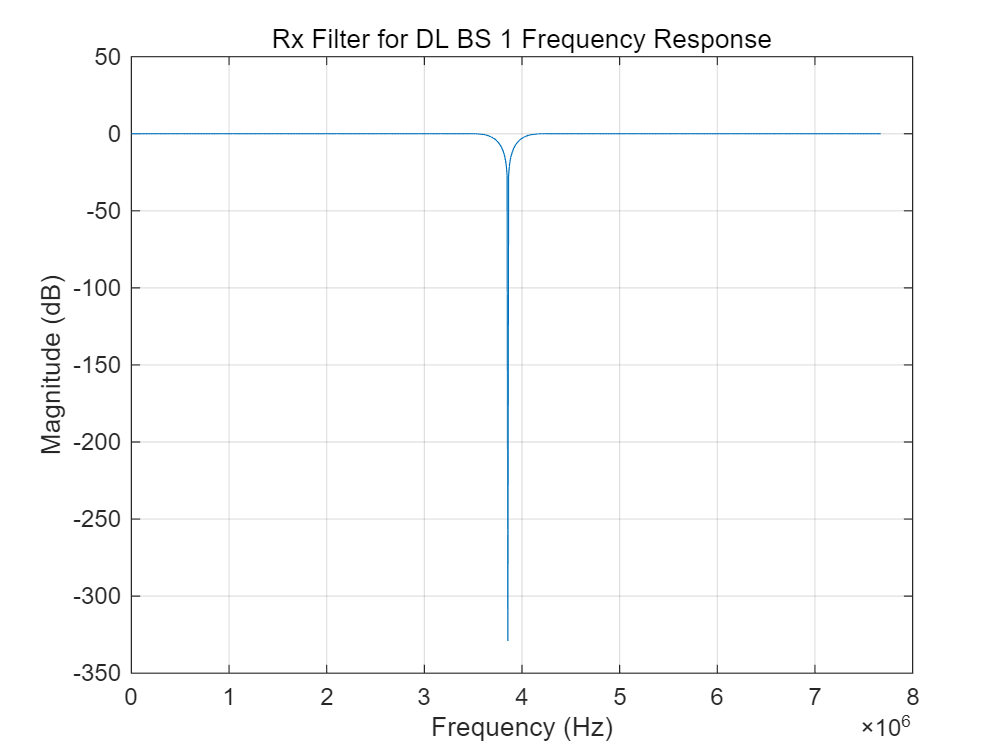

channelmapping         = 1;  % mutichannel or single channel selection
watch_filteredResult   = false;

% cfg 用来配置是否进行burst传输、CFO、CPE、信道均衡操作，显示示波器，可视化计算结果等。
cfg.enableBurstMode      = true;                    % 是否选择进行突发接收（适当的采用burst传输以避免overflow，true表示启用burst传输，不是实时的，False表示禁用burst传输，是实时的）
cfg.burstbuffersize      = 30;   % 设定突发传输的buffer大小（一个buffer的总帧数）

cfg.enableCFO            = true;
cfg.enableCPE            = false;
cfg.enableChest          = true;
cfg.enableHeaderCRCcheck = true;

cfg.enableTimescope      = false;
cfg.enableScopes         = true;
cfg.verbosity            = false;
cfg.printData            = false;
cfg.enableConst_measure  = true;

% 接下来是针对UE B210联合分别接收不同基站数据的radio设置和具体接收算法流程+resource OFDM parameters
overAllOfdmParams.Rcv_DL_CoopBSs_id                   = [1];                %当前服务该用户的下行基站协作集, 接收BS id信号处理的顺序与list前后顺序一致
overAllOfdmParams.PilotSubcarrierSpacing              = [36];              % Pilot sub-carrier spacing
overAllOfdmParams.BWPoffset                           = [0];                %当前基站的总带宽offset（单位/1个子载波），offset设置的是实际带宽start位置相对于初始计算的start的位置的偏移
UE_id                                                 = 1;                    %当前UE的ID标识符
% 根据全局configure和特定配置，初始化所有接收下行基站的 sysParam、rxObj、OFDMParams、dataParams等参数保存至sysParamRxObj
sysParamRxObj = setupSysParamsAndRxObjects(overAllOfdmParams, cfg);

% 检查 sysParamRxObj 中所有基站的 field names和预先确定的overAllOfdmParams中协作基站集ID名称和顺序是否一致
BS_fieldnames = fieldnames(sysParamRxObj);

% read_savedData = false %from bbr()
% if read_savedData
%     radioDevice            = "B210";   % Choose radio device for reception
%     centerFrequency        = 2.2e9;
%     gain                   = 55; % Set radio gain
%     read_filename = 'received_buffer.bb'; 
%     % 初始化接收机USRP radio和软接收object basbandreceiver bbr
%     radio = GetRxUsrpRadioObj(sysParamRxObj,radioDevice,centerFrequency,gain,channelmapping,read_savedData,read_filename);
% end

% 初始化所有基站的可视化工具
visualizationTools = setupVisualizationTools(sysParamRxObj);
% 初始化计算误码率对象
errorRate_collection = struct();  % 结构体保存每个基站的误码率对象
for index = 1:length(BS_fieldnames)
    % 为每个基站初始化误码率对象，并保存到 BER_objects 结构体中
    current_BS_field = BS_fieldnames{index};
    errorRate_collection.(current_BS_field) = comm.ErrorRate();
end

## Execute Receiver Loop

#### Synchronization

#### Frequency Offset Estimation and Correction

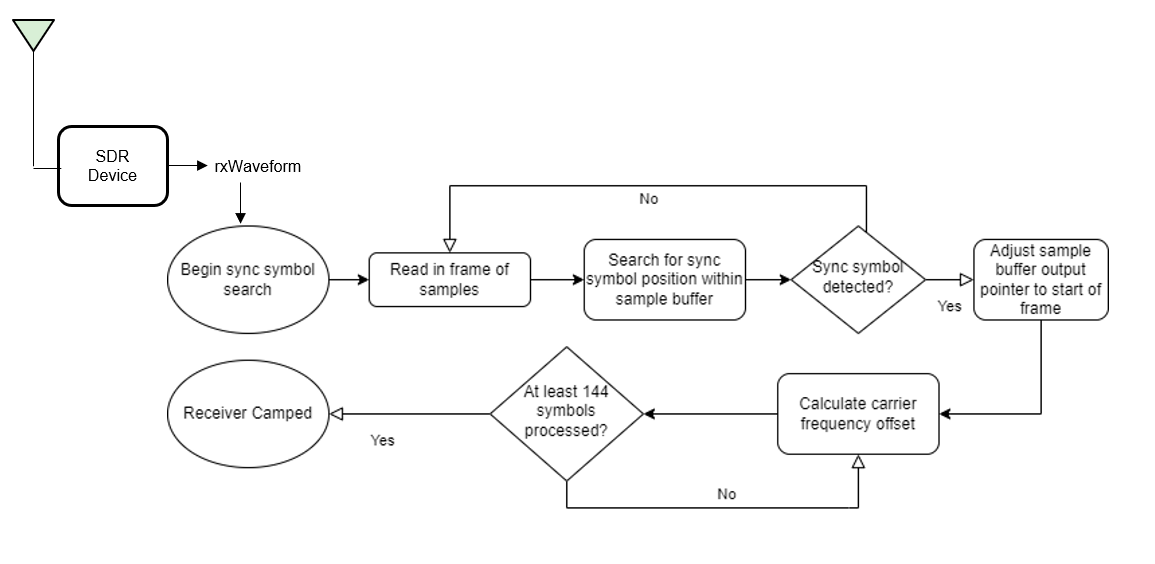

### Receiver Processing

#### Channel Estimation and Equalization

#### Header Decoding

#### Data Decoding

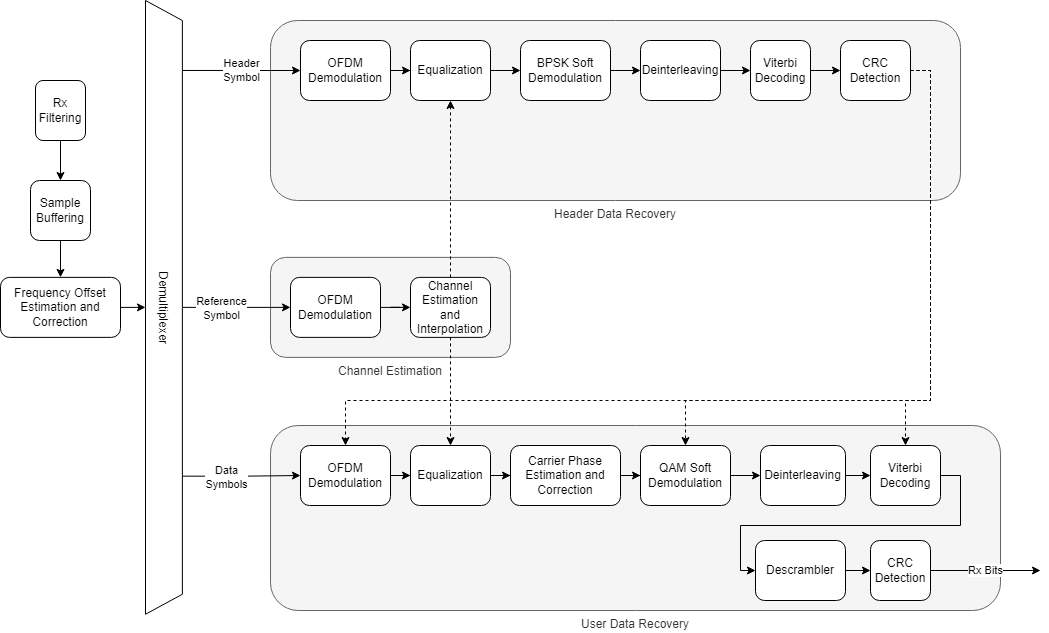

BER_collection = struct();
EVM_collection = struct();
MER_collection = struct();
RSSI_collection = struct();
isConnected = false;

% 初始化变量用于计算速率
totalBitsReceivedPerBS = zeros(1, length(BS_fieldnames));    % 每个基站每帧接收到的总比特数
previousTimePerBS = struct();                           % 记录每个基站计算速率的起始时间
currentTimePerBS = struct();                            % 记录每个基站计算速率的终了时间
dataRateCollection = struct();                          % 保存每个基站和总的速率
peakRatePerBS = zeros(1, length(BS_fieldnames));        % 每个基站的峰值速率

totalMemorySizeInGB = 4;  % 4GB
totalMemorySizeInBytes = totalMemorySizeInGB * (1024^3);  % 4GB in bytes
numElements = totalMemorySizeInBytes/(8*2);

framesize = sysParamRxObj.(current_BS_field).sysParam.txWaveformSize;
samplerate = sysParamRxObj.(current_BS_field).sysParam.SampleRate;
timePerFrame = framesize / samplerate; 

% 是否根据给定时间传输。若为false，则指定帧数传输。
% 在本程序：从内存中读取数据进行后续信号处理解调中，默认为false，即指定处理的帧数
enable_time_limit_transmission = false;
if enable_time_limit_transmission
    %指定要进行信号处理的总时间
    rcvtime = 15;       % units: seconds
    numFrame = floor(rcvtime/timePerFrame);
else
    %指定要进行信号处理的帧数
    numFrame = 500;  
end

% 计算总接收时间 (秒)
totalTime = numFrame * timePerFrame;
[maxRcvFrames, maxRcvTime] = calculateTotalFramesAndTime(totalMemorySizeInGB, framesize, samplerate);
fprintf('buffer能处理的最大总帧数：%d / 当前处理总帧数: %d\n', maxRcvFrames, numFrame);

buffer能处理的最大总帧数：27962 / 当前处理总帧数: 500


fprintf('buffer能处理的最大总处理时间：%.2f 秒 / 当前总处理时间: %.2f 秒\n', maxRcvTime, totalTime);

buffer能处理的最大总处理时间：34.95 秒 / 当前总处理时间: 0.62 秒


[DL_BS_1]Sync symbol found.
[DL_BS_1]Estimating carrier frequency offset ...
[DL_BS_1]Receiver camped.
.........................................................................
................................................................................
................................................................................
................................................................................
................................................................................
................................................................................
....................

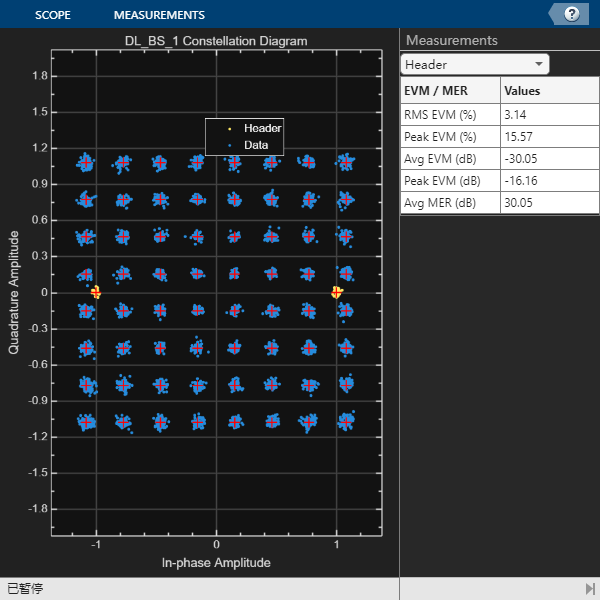

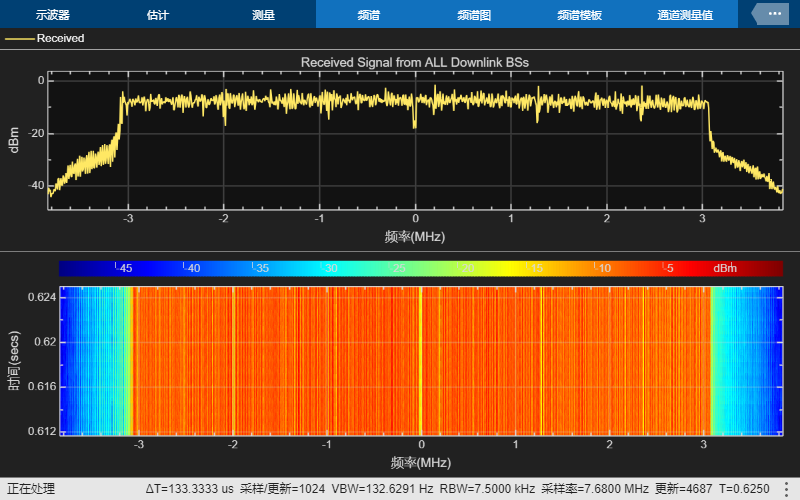

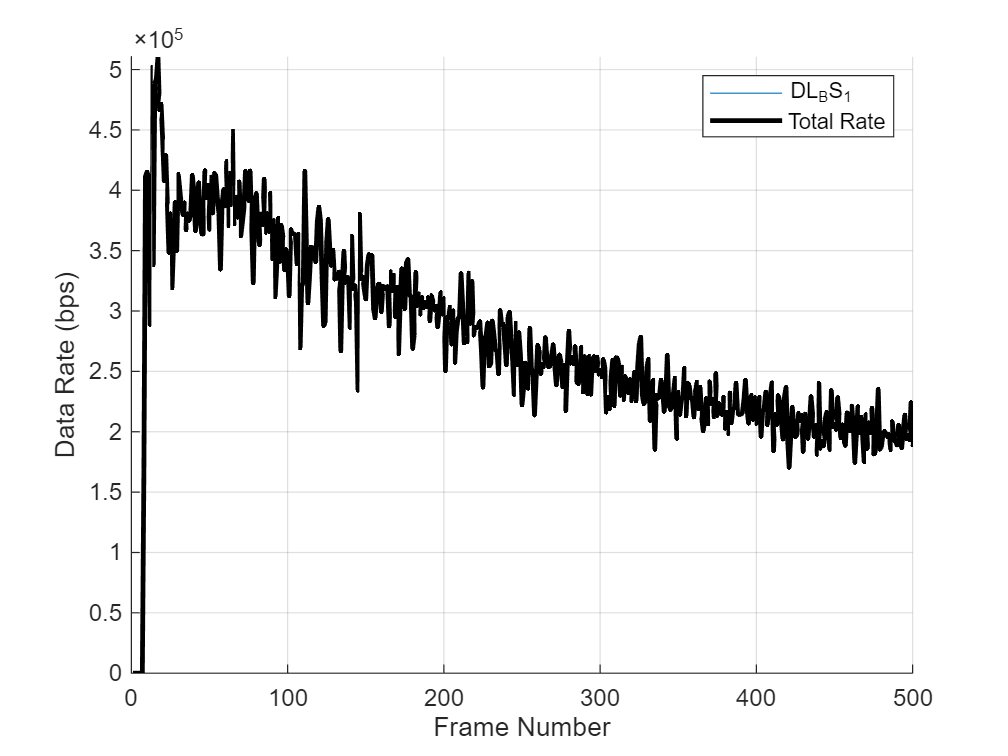

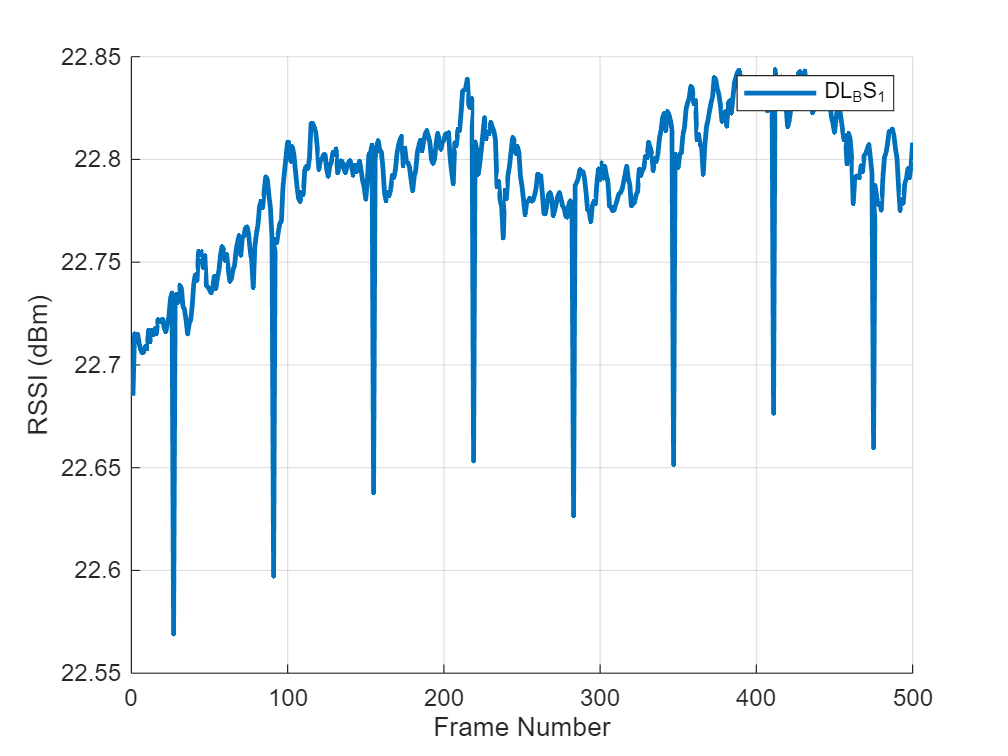

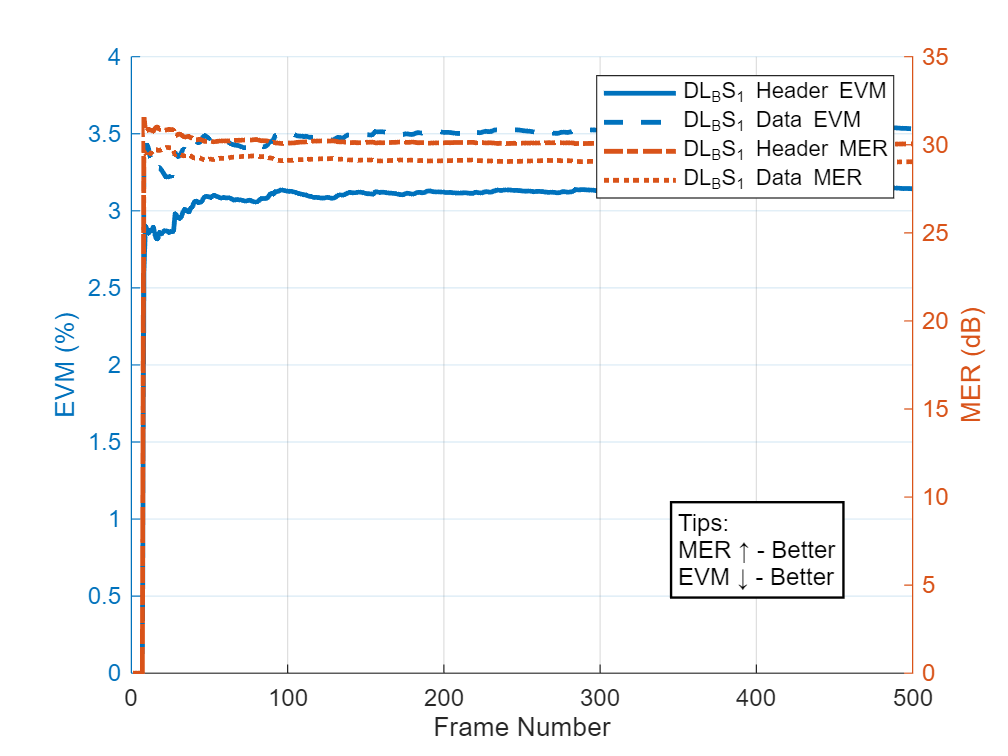

if numFrame > maxRcvFrames
    error('set received total frame length (%d) exceeds max length of buffer (%d) for receiving!',numFrame,maxRcvFrames)
end
if totalTime > maxRcvTime
    error('set received total time (%.3f) exceeds max time length of buffer (%.3f) for receiving!',totalTime,maxRcvTime)
end

% 提前计算每帧的开始和结束索引
startIdxList = (0:numFrame-1) * framesize + 1;
endIdxList = startIdxList + framesize - 1;

% Memory map file
root = "E:\FDRAN_Prototype\cache_file\";
filename = root + "received_buffer.bin";
m = memmapfile(filename, ...
    'Format', {'double', [numElements, 2], 'complexData'});

% 初始化每个基站的独立速率存储
for index = 1:length(BS_fieldnames)
    current_BS_field = BS_fieldnames{index};
    dataRateCollection.(current_BS_field) = zeros(1, numFrame);  % 用于保存每帧速率
end
dataRateCollection.total = zeros(1, numFrame);  % 总速率

% 循环遍历每个帧
for frameNum = 1:numFrame
    % [rxWaveform, ~, overflow] = radio();  % 从无线电设备中读取数据
    % 从内存映射文件中读取指定帧的数据
    startIdx = startIdxList(frameNum);
    endIdx = endIdxList(frameNum);

    % 读取并重构为复数信号
    rxWaveform =complex(m.Data.complexData(startIdx:endIdx, 1), m.Data.complexData(startIdx:endIdx, 2));

    % 生成 rxWaveform 的多个副本，数量为基站数量
    numBSs = length(BS_fieldnames);
    rxWaveformCopies = cell(1, numBSs);
    for i = 1:numBSs
        rxWaveformCopies{i} = rxWaveform;  % 为每个基站生成副本
    end

    if isConnected && cfg.verbosity
        fprintf('____________________________________________________________________________\n')
    end


    % 遍历协作基站集
    for index = 1:length(BS_fieldnames)
        % 获取对应基站的部分参数用于后续计算
        current_BS_field = BS_fieldnames{index};
        transportBlk_bs = sysParamRxObj.(current_BS_field).transportBlk_bs;
    
        % 初始化保存每个基站每帧BER、EVM、MER、RSSI的结构体
        if ~isfield(BER_collection, current_BS_field)
            BER_collection.(current_BS_field) = zeros(1, numFrame);
            RSSI_collection.(current_BS_field) = zeros(1, numFrame);  % 前30 帧     
            EVM_collection.(current_BS_field).header = zeros(1, numFrame);  
            EVM_collection.(current_BS_field).data = zeros(1, numFrame);
            MER_collection.(current_BS_field).header = zeros(1, numFrame);
            MER_collection.(current_BS_field).data = zeros(1, numFrame);
        end
        
        % 从副本中获取当前基站对应的 rxWaveform
        rxWaveform_for_currentBS = rxWaveformCopies{index};
        
        % 运行接收前端
        rxIn = helperOFDMRxFrontEnd(rxWaveform_for_currentBS, ...
            sysParamRxObj.(current_BS_field).sysParam, ...
            sysParamRxObj.(current_BS_field).rxObj, ...
            visualizationTools.(current_BS_field).spectrumAnalyze, ...
            watch_filteredResult);

        % 运行接收处理
        previousTimePerBS.(current_BS_field) = tic;
        [rxDataBits, isConnected, toff, rxDiagnostics] = helperOFDMRx(rxIn, ...
            sysParamRxObj.(current_BS_field).sysParam, ...
            sysParamRxObj.(current_BS_field).rxObj, ...
            visualizationTools.(current_BS_field).timesink, frameNum);
        currentTimePerBS.(current_BS_field) = toc(previousTimePerBS.(current_BS_field));
        sysParamRxObj.(current_BS_field).sysParam.timingAdvance = toff;

        % 收集误码率和帧错误统计
        if isConnected
            % 更新误码率
            berVals_bs = errorRate_collection.(current_BS_field)(transportBlk_bs((1:sysParamRxObj.(current_BS_field).sysParam.trBlkSize)).', rxDataBits);
            BER_collection.(current_BS_field)(frameNum) = berVals_bs(1);
            totalBitsReceivedPerBS(index) = length(rxDataBits);

            if sysParamRxObj.(current_BS_field).dataParams.printData
                % 打印接收到的数据
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits), 7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode), 7, []), 7));
                fprintf('[%s]Received data in frame %d from %s: %s\n', current_BS_field, frameNum, current_BS_field, recData);
            end
    
            % 计算数据速率（比特每秒）
            dataRate = totalBitsReceivedPerBS(index) / currentTimePerBS.(current_BS_field);  % bps
            
            % 更新当前基站的峰值速率
            if dataRate > peakRatePerBS(index)
                peakRatePerBS(index) = dataRate;
            end

            % 保存当前的数据速率
            dataRateCollection.(current_BS_field)(frameNum) = dataRate;

        end

        % 计算 RSSI
        if sysParamRxObj.(current_BS_field).dataParams.enableConst_measure
            RSSI_collection.(current_BS_field)(frameNum) = 10 * log10(mean(abs(rxWaveform_for_currentBS).^2)) + 30;  % 计算 dBm 值
        end

        % 计算 EVM 和 MER
        if isConnected && sysParamRxObj.(current_BS_field).dataParams.enableConst_measure
            % 计算并保存每帧的 EVM、MER和RSSI
            EVM_collection.(current_BS_field).header(frameNum) = visualizationTools.(current_BS_field).constellation_measure.evm_header( ...
                complex(rxDiagnostics.rxConstellationHeader(:)));
            EVM_collection.(current_BS_field).data(frameNum) = visualizationTools.(current_BS_field).constellation_measure.evm_data( ...
                complex(rxDiagnostics.rxConstellationData(:)));
            MER_collection.(current_BS_field).header(frameNum) = visualizationTools.(current_BS_field).constellation_measure.mer_header( ...
                complex(rxDiagnostics.rxConstellationHeader(:)));
            MER_collection.(current_BS_field).data(frameNum) = visualizationTools.(current_BS_field).constellation_measure.mer_data( ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        % 显示星座图
        if isConnected && sysParamRxObj.(current_BS_field).dataParams.enableScopes
            visualizationTools.(current_BS_field).constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), complex(rxDiagnostics.rxConstellationData(:)));
        end  
    end
    % 计算当前帧下联合接收所有基站的总速率,计算联合速率 (bps)
    totalBitsReceived = sum(totalBitsReceivedPerBS);  % 所有基站的总比特数
    totaltime = sum(struct2array(currentTimePerBS));  % 总时间
    totalDataRate = totalBitsReceived / totaltime;
    dataRateCollection.total(frameNum) = totalDataRate;

    % 显示频谱分析
    if sysParamRxObj.(current_BS_field).dataParams.enableScopes && ~watch_filteredResult
        visualizationTools.(current_BS_field).spectrumAnalyze.Title = 'Received Signal from ALL Downlink BSs';
        visualizationTools.(current_BS_field).spectrumAnalyze(rxWaveform);
    end
    % 画速率和RSSI曲线图
    if sysParamRxObj.(current_BS_field).dataParams.enableScopes
        plotDataRates(BS_fieldnames,dataRateCollection,frameNum,numFrame)
        plotRSSI(BS_fieldnames, RSSI_collection, frameNum, numFrame);
        plotEVMandMER(BS_fieldnames, EVM_collection, MER_collection, frameNum, numFrame);
    end
end



fprintf(['----------------------------\n' ...
    'Simulation complete!\n' ...
    '----------------------------\n'])

----------------------------
Simulation complete!
----------------------------





% 显示每个基站的平均 BER 值和 EVM、MER 测量结果
for index = 1:length(BS_fieldnames)
    current_BS_field = BS_fieldnames{index};
    Length = length(current_BS_field);          % 用于输出对齐
        
    avg_BER         = mean(BER_collection.(current_BS_field));           % 计算当前基站平均BER
    avgRatePerBS    = mean(dataRateCollection.(current_BS_field));       % 计算当前基站平均速率
    avgRSSI         = mean(RSSI_collection.(current_BS_field));          % 计算当前基站平均RSSI
    
    fprintf('-------measurement-------\n')
    fprintf('%s Measurement:\n', current_BS_field);
    % fprintf('%s Average BER = %.4e\n', current_BS_field, avg_BER);
    fprintf(['%' num2str(Length) 's Average BER = %.4e\n'], '', avg_BER);
    fprintf(['%' num2str(Length) 's Average Data Rate: %.4e bps\n'], '', avgRatePerBS);
    fprintf(['%' num2str(Length) 's Peak Data Rate: %.4e bps\n'], '', peakRatePerBS(index));
    fprintf(['%' num2str(Length) 's Average RSSI: %.4f dBm\n'], '', avgRSSI);

    % 平均 EVM 和 MER
    avg_EVM_header = mean(EVM_collection.(current_BS_field).header);
    avg_EVM_data = mean(EVM_collection.(current_BS_field).data);
    avg_MER_header = mean(MER_collection.(current_BS_field).header);
    avg_MER_data = mean(MER_collection.(current_BS_field).data);

    fprintf(['%' num2str(Length) 's Header rms EVM(%%): %.3f %%\n'], '', avg_EVM_header);
    fprintf(['%' num2str(Length) 's Data rms EVM(%%): %.3f %%\n'], '', avg_EVM_data);
    fprintf(['%' num2str(Length) 's Header MER(dB): %.3f dB\n'], '', avg_MER_header);
    fprintf(['%' num2str(Length) 's Data MER(dB): %.3f dB\n \n'], '', avg_MER_data);
    if index == length(BS_fieldnames)
        % 计算并打印总的平均和峰值速率
        avgTotalRate = mean(dataRateCollection.total);
        peakTotalRate = max(dataRateCollection.total);
        fprintf('Total Average Data Rate: %.4e bps\n', avgTotalRate);
        fprintf('Total Peak Data Rate: %.4e bps\n', peakTotalRate);
    end
end

-------measurement-------


DL_BS_1 Measurement:


        Average BER = 0.0000e+00


        Average Data Rate: 2.7647e+05 bps


        Peak Data Rate: 5.1064e+05 bps


        Average RSSI: 22.7902 dBm


        Header rms EVM(%): 3.065 %


        Data rms EVM(%): 3.446 %


        Header MER(dB): 29.729 dB


        Data MER(dB): 28.726 dB
 


Total Average Data Rate: 2.7647e+05 bps


Total Peak Data Rate: 5.1064e+05 bps



% 释放资源
% release(radio);

%% 
function [totalFrames, totalTime] = calculateTotalFramesAndTime(totalMemorySizeInGB, framesize, samplerate)
    % 计算内存大小 (单位：字节)
    totalMemorySizeInBytes = totalMemorySizeInGB * (1024^3);
    
    % 每帧包含的字节数：每帧有 framesize 个复数采样点，每个复数采样点有两个 double（实部和虚部），每个 double 占用 8 字节
    bytesPerFrame = framesize * 2 * 8;
    
    % 计算总帧数
    totalFrames = floor(totalMemorySizeInBytes / bytesPerFrame);
    
    % 每帧的持续时间 (秒)
    timePerFrame = framesize / samplerate;
    
    % 计算总接收时间 (秒)
    totalTime = totalFrames * timePerFrame;
end